# Compare the interpolated signal with the measured signal using the code of Aaron Geldert

clc
clear all

% original datapoint
load("rt40_mat_files\DOA_rt40.mat");
load("rt40_mat_files\pressure_rt40.mat");

start = 200;
size = 1000;
end_index = size + start - 1;

P{1,1} = P{1,1}(start:end_index,:);
P{3,1} = P{3,1}(start:end_index,:);

DOA{1,1} = DOA{1,1}(start:end_index,:);
DOA{3,1} = DOA{3,1}(start:end_index,:);

SDM1 = struct('fs',48000,'pos',DOA{1,1},'mass',P{1,1},'tVec',1,'n',size)

SDM1 = struct with fields:
      fs: 48000
     pos: [1000×3 double]
    mass: [1000×1 double]
    tVec: 1
       n: 1000


SDM2 = struct('fs',48000,'pos',DOA{3,1},'mass',P{3,1},'tVec',1,'n',size)

SDM2 = struct with fields:
      fs: 48000
     pos: [1000×3 double]
    mass: [1000×1 double]
    tVec: 1
       n: 1000


SDMint = interpolateSDM(SDM1, SDM2)

 
d =
 
    cvx real affine expression (1001x1001 matrix)
 
 
Calling SeDuMi 1.3.4: 1002001 variables, 2003 equality constraints
------------------------------------------------------------
SeDuMi 1.3.4 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 2003, order n = 1.002e+06, dim = 1.002e+06, blocks = 1
nnz(A) = 3004002 + 0, nnz(ADA) = 2010005, nnz(L) = 1506505
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.21E+07 0.000
  1 :  -1.15E+06 9.92E+02 0.000 0.0000 1.0000 1.0000  -1.00  1  1  3.8E+05
  2 :  -4.55E+05 2.21E+02 0.000 0.2227 0.9000 0.9000   1.52  1  1  6.6E+04
  3 :   3.41E+06 6.96E-01 0.000 0.0032 0.9990 0.9990   0.03  1  1  4.0E+03
  4 :   2.59E+13 9.47E-08 0.000 0.0000 1.0000 1.0000  -1.00  1  1  
Primal infeasible, dual improving direction found.
iter seconds  |Ax|    [Ay]_+     |x|       |y|
  4      6.5   0.0e+00   0.0e+00   0.0e+00   5.0

SDMint = struct with fields:
      fs: 48000
    tVec: 1
     pos: [1002000×3 double]
    dist: [1002000×1 double]
    mass: [1002000×1 double]
       n: 1002000


fs = SDMint.fs

fs = 48000

a = createSDMStruct('DefaultArray','GRASVI50','fs',fs,'winLen',15);

User-defined SDM Settings are used :
           fs: 48000
            c: 345
       winLen: 15
    parFrames: 8192
    showArray: 0
      micLocs: [6×3 double]



v = createVisualizationStruct('DefaultRoom','LargeRoom',...
    'name','ESAT STADIUS Lab','fs',fs,'t',[2 5 10 20 50 100 200 2000]);

createVisualizationStruct : User-defined visualization settings are used :
              fs: 48000
           plane: 'lateral'
             DOI: 'forward'
       plotStyle: 'line'
            name: 'ESAT STADIUS Lab'
             res: 1
               t: [2 5 10 20 50 100 200 2000]
          colors: [8×3 double]
       dBSpacing: 6
      DOASpacing: 30
      dBDynamics: 45
       linewidth: [1 1 1 1 1 1 1 1]
        showGrid: 1
    smoothMethod: 'average'
       smoothRes: 3



% For visualization purposes, set the text interpreter to latex
set(0,'DefaultTextInterpreter','latex')
parameterVisualization(P(2,1), v);

Started visualization of parameters.
Ended visualization of parameters in 0.38539 seconds.


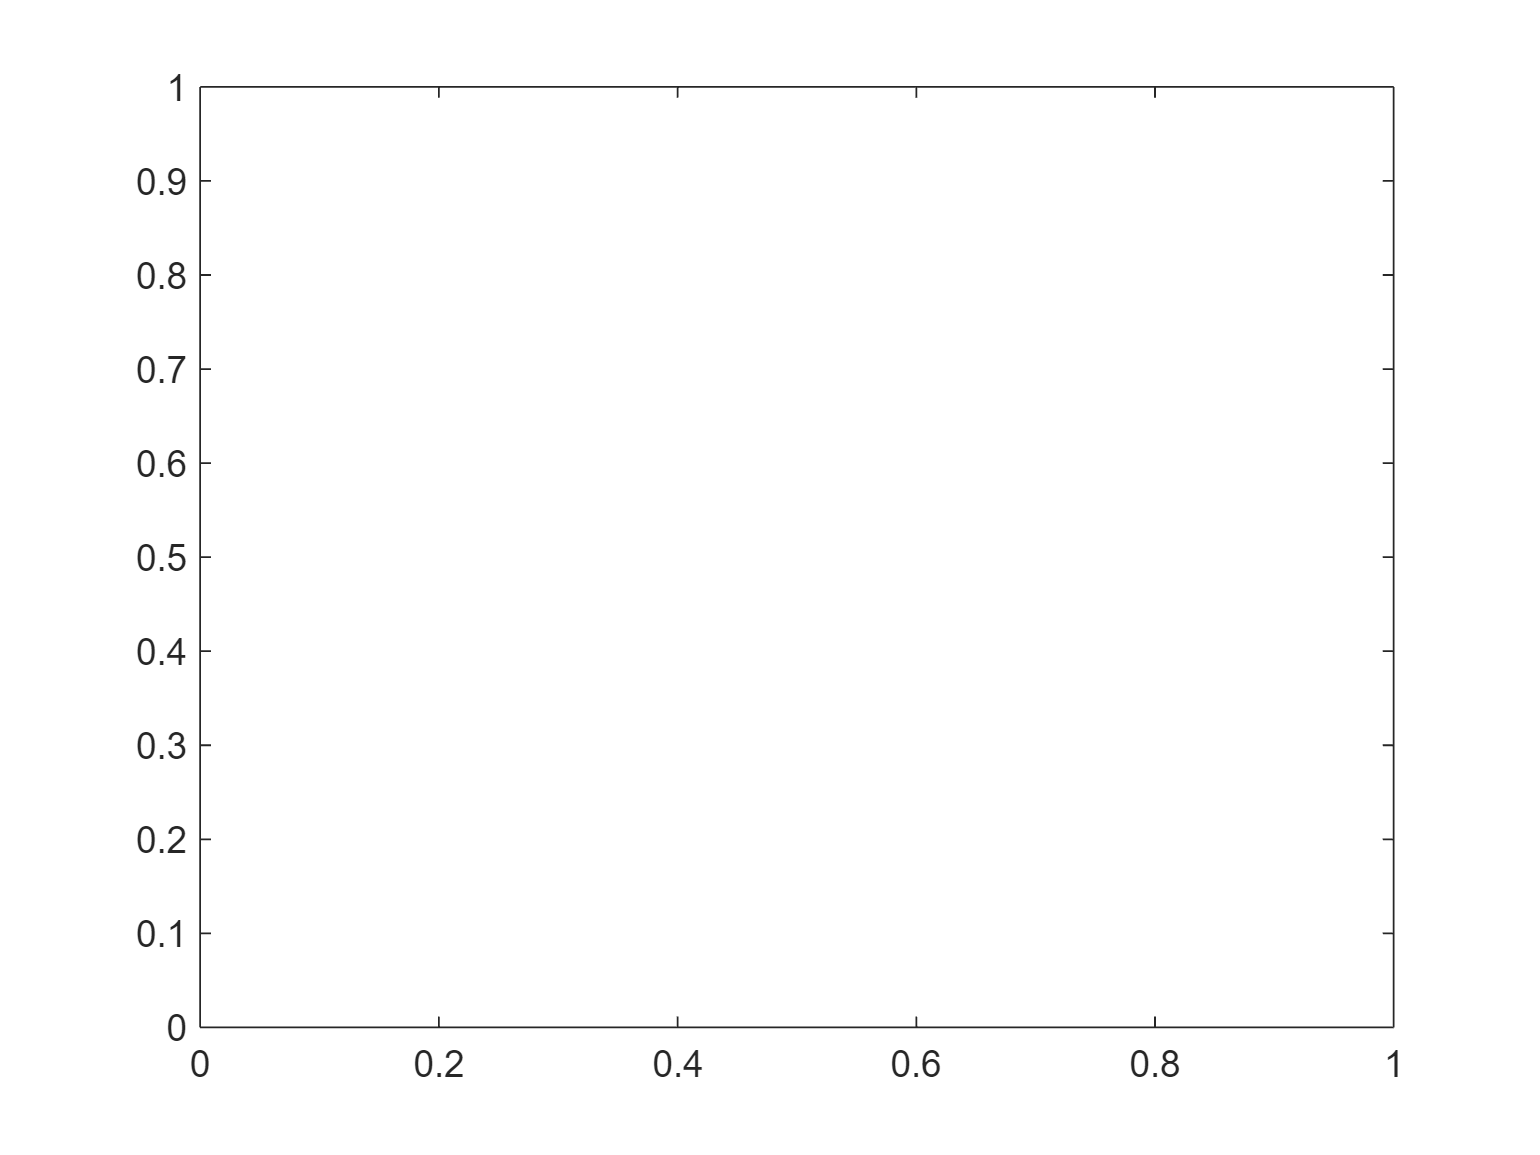

plot(SDMint.mass)

timeFrequencyVisualization(P(2,1), v);
%timeFrequencyVisualization(SDMint.mass, v);

v.plane = 'lateral';
% Original second measurement
spatioTemporalVisualization(P(2,1), DOA(2,1), v)
spatioTemporalVisualization(SDMint.mass, SDMint.pos, v)

v.plane = 'transverse';
% Original
spatioTemporalVisualization(P(2,1), DOA(2,1), v)
spatioTemporalVisualization(SDMint.mass, SDMint.pos, v)

v.plane = 'median';
% Original
spatioTemporalVisualization(P(2,1), DOA(2,1), v)
spatioTemporalVisualization(SDMint.mass, SDMint.pos, v)